# **Examples**

## Example 1

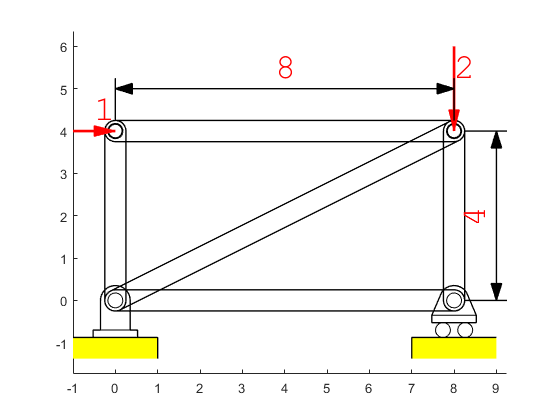

drawInit
ht = 0.5;hs = 0.7*ht;F=1;d1=8;d2=4;
% draw truses
drawCanoe1( ht, 0,0,d1,0 );
drawCanoe1( ht, d1,0,d1,d2 );
drawCanoe1( ht, 0,0,d1,d2 );
drawCanoe1( ht, 0,d2,d1,d2 );
drawCanoe1( ht, 0,0,0,d2 );
% draw pins
drawDonut(hs,0.9*hs,0,d2);
drawDonut(hs,0.9*hs,d1,d2);
% draw supports
s1 = drawSupport(1,hs,0,0);
s2 = drawSupport(2,hs,d1,0);
% draw floor
fillRect('y',d2*ht,ht,s1.xk(3),s1.yk(3),'-pos',d1)
fillRect('y',d2*ht,ht,s2.xk(3),s2.yk(3),'-pos',d1)
drawRect(d2*ht,ht,s1.xk(3),s1.yk(3),'-pos',d1,'-v',2,4)
drawRect(d2*ht,ht,s2.xk(3),s2.yk(3),'-pos',d1,'-v',3,1)
% draw forces
f1=drawForce(F,180,0,0,d2,'-ad',0.5,'r','LineWidth',2);
f2=drawForce(2*F,90,0,d1,d2,'-ad',0.5,'r','LineWidth',2);
drawText(f1.xk(3),f1.yk(3),num2str(F));
drawText(f2.xk(3),f2.yk(3),num2str(2*F));
% dimension
drawVDim(3,0.8*ht,ht/2,d1,0,d1,d2,d1+1,d2/2)
drawHDim(3,0.8*ht,ht/2,0,d2,d1,d2,d1/2,d2+1)

drawShow


## Example 2

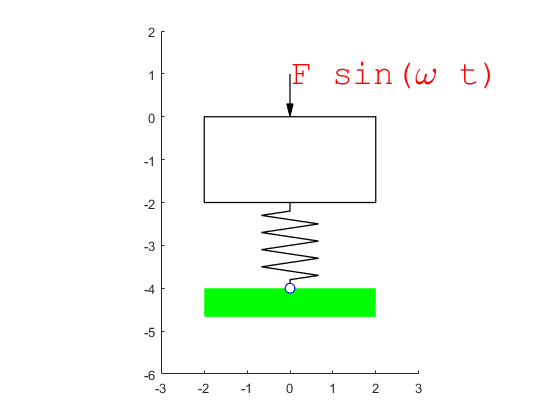

% animatio outside Live script
h = 2;w=4;
fg=drawInit;
drawInit(fg)
drawLimits(-3,3,-6,2)
r = drawRect(w,h,0,0,'-pos',8);
s=drawSpring1(2,h/3,4,r.xk(2),r.yk(2),r.xk(2),-2*h);
f = drawForce(1,90,0,0,0,'-ad',0.3);
fillRect('g',w,h/3,s.xk(2),s.yk(2),'-pos',8)
fillDonut('b','w',h/8,h/10,s.xk(2),s.yk(2))
drawText(f.xk(3),f.yk(3),'F sin(\omega t)')

## Example 3

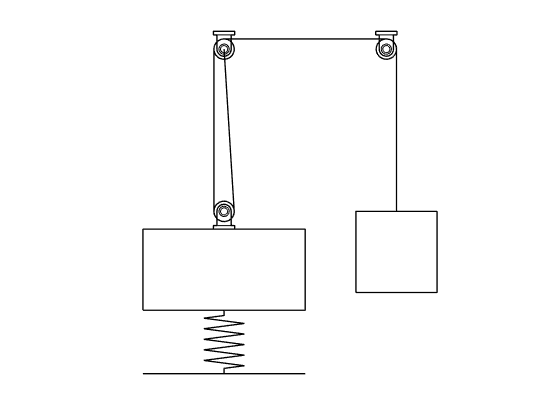

d1 = 0.5;wd=4;ht=2;h=2+ht;y=0;
drawInit
axis off
c1=drawDonut(d1,d1/2,0,y);
s1 = drawSupport(1,0.7*d1/2,0,y);
r1 = drawRect(wd,ht,s1.xk(3),s1.yk(3),'-pos',8);
sp = drawSpring1(2,d1,5,r1.xk(2),r1.yk(2),r1.xk(2),-h);
drawLine( sp.xk(2),sp.yk(2),'-delta',1,0,-wd/2,2)
s2 = drawSupport(1,0.7*d1/2,0,h,-180);
c2=drawDonut(d1,d1/2,0,h);
s3 = drawSupport(1,0.7*d1/2,wd,h,-180);
c3=drawDonut(d1,d1/2,wd,h);
drawLine(c1.xk(1),c1.yk(1),c2.xk(1),c2.yk(2))
drawLine(c1.xk(2),c1.yk(2),c2.xk(5),c2.yk(5))
drawLine(c2.xk(4),c2.yk(4),c3.xk(4),c3.yk(4))
L1=drawLine(c3.xk(2),c3.yk(2),'-delta',0,-h-y);
drawRect(ht,ht,L1.xk(2),L1.yk(2),'-pos',8)

drawShow